# Predictive Control for Cobot Safety

*Could add in a short introductory description of the aims of the project and such*

## Robot Plant and Initial Conditions

clc;

Load the KINOVA Gen 3 robot manipulator multibody model and rigid body tree.

[robotRBT, robotInformation] = loadrobot("kinovaGen3", DataFormat="column", Gravity=[0 0 -9.81]);

Define key robot parameters that will be used further on. The quantity of joints and the end-effector (tool) element of the rigid body tree.

joint_qty = numel(homeConfiguration(robotRBT));
endEff = 'EndEffector_Link';

Prepare inverse kinematic equations to compute robot configurations given end-effector poses.

robot_InverseKinematics = inverseKinematics("RigidBodyTree", robotRBT);
robot_InverseKinematics.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

Define initial and final trajectory task-space coordinates. The initial position may be given as a complete robot configuration while the final position is a desired end-effector pose (other joint positions in the task-space are irrelevant).

qInit = [0 0 0 0 0 0 0]'*pi/180; % initial joint configuration in radians
taskInit = getTransform(robotRBT, qInit, endEff); % initial transformation matrix of task
coordStart = taskInit(1:3, 4); % initial task-space end-effector coordinates XYZ
xInit = [qInit', zeros(1, joint_qty)]; % initial robot state [q, dq]

taskEnd = trvec2tform([0.6 0.4 0.3])*axang2tform([0 1 0 pi]); % final task-space end-effector coordinates XYZ
anglesEnd = rotm2eul(taskEnd(1:3, 1:3), "XYZ"); % final task-space end-effector rotational coordinates [phi theta psi]
poseEnd = [taskEnd(1:3, 4); anglesEnd']; % final pose vector [X Y Z phi theta psi]

## Static and Dynamic Obstacles

Generate static obstacles that represent elements of the environment.

safety_dist = 0.1;
staticObstacleGeneration;

Define primary task-driven waypoints for the dynamic obstacle. In this case, the representative collaborative partner and obstacle will be a robot model aiming to reach the waypoints with an end-tool.

task_waypoints = [0.6 0.3 0.3 0 1 0 pi;     % PosX PosY PosZ RotX RotY RotZ rotationAngle
    0.4 -0.1 0.3 0 1 0 pi;
    0.2 -0.2 0.4 0 1 0 pi/2; 
    0.2 -0.2 0.7 0 1 0 pi/2;
    0.4 -0.3 0.8 0 1 0 pi/2;
    0.2 -0.4 0.7 0 1 0 pi/2;
    0.2 -0.4 0.4 0 1 0 pi;
    0.4 -0.5 0.3 0 1 0 pi;
    0.5 0.1 0.3 0 1 0 pi;
    0.6 0.3 0.3 0 1 0 pi];

Generate dynamic obstacle representing the collaborative element to the plant. This model will represent a human working alongside the KinovaGen3 robot.

[obst_robot, ~] = loadrobot("kinovaGen3", DataFormat="column", Gravity=[0 0 -9.81]);

Generate the task trajectory for the obstacle robot to follow desired waypoints during the simulation.

dynamicObstacleTrajectoryGeneration;

## Initial Visualization

Generate a 3D graphical visualization of the initial task-space environment, robot configurations, task trajectory of the obstacle robot, and start and end goals.

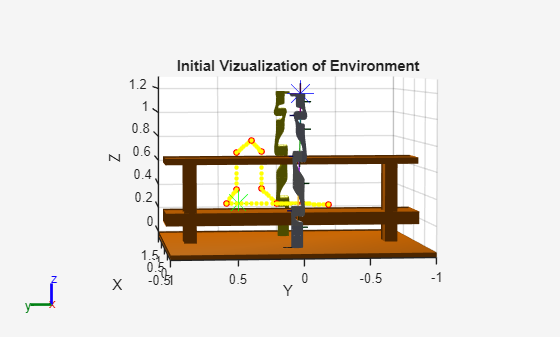

generateTaskEnvironment(robotRBT, qInit, coordStart, poseEnd, staticObst, obst_robot, task_waypoints, ...
    waypoints, 'Robot and Obstacle Conditions', 'Initial Vizualization of Environment')

## Design: PID Control

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

Generate visualizations for the initial environment objects.

generateTaskEnvironment(robotRBT, qInit, coordStart, poseEnd, staticObst, obst_robot, task_waypoints, ...
    waypoints, 'Task Simulation', 'Task Simulation', true);

Simulate task dynamics and control responses of the obstacle robot and robot of interest.

% runSimulationLoop;

## Design: Linear MPC

generateMPC;

-->"PredictionHorizon" is empty. Assuming default 10.
-->"ControlHorizon" is empty. Assuming default 2.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


### Closed-Loop Trajectory Planning

obstacles = staticObst;
% obst_bodies = obst_robot.Bodies;
% 
% for i=1:length(obst_bodies)
%     if ~isempty(obst_bodies{i}.Collisions)
%         obst_transform = getTransform(obst_robot, robotStateAll(1,1:7)', obst_bodies{i}.Name);
%         for j=1:length(obst_bodies{i}.Collisions)
%             collision_obj = obst_bodies{i}.Collisions{j};
%             collision_obj.Pose = obst_transform * obst_bodies{i}.Collisions{j}.Pose;
% 
%             obstacles{end+1} = collision_obj;
%         end
%     end
% end

Simulation initial conditions

maxIteration = 50;
uInit = zeros(1, joint_qty);
ym = uInit;
xc = mpcstate(mpc_obj);

-->Converting model to discrete time.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #2.
   Assuming no disturbance added to measured output #3.
   Assuming no disturbance added to measured output #4.
   Assuming no disturbance added to measured output #5.
   Assuming no disturbance added to measured output #6.
   Assuming no disturbance added to measured output #7.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


xc.Plant = xInit;
time = 0;
goalReached = false;

Initialize data matrices

positions = zeros(joint_qty, maxIteration);
positions(:,1) = xInit(1:joint_qty)';

velocities = zeros(joint_qty, maxIteration);
velocities(:,1) = xInit(joint_qty+1:end);

accelerations = zeros(joint_qty, maxIteration);
accelerations(:,1) = uInit';

timeStep = zeros(1, maxIteration);
timeStep(:,1) = time;

[qr, ~] = robot_InverseKinematics(endEff, taskEnd, weights, qInit);
r = repmat(qr', mpc_obj.PredictionHorizon, 1);

for iteration=1:maxIteration
    disp(['Calculating control at timestep: ', num2str(iteration)])
    
    % optimize next trajectory point
    [ym, info] = mpcmove(mpc_obj, xc, ym, r, []); % no reference yet

    % check for failed trajectory generations
    if info.Iterations < 0
        disp('Failed to compute a feasible trajectory. Aborting...')
        break
    end

    % update states and time
    x = info.Xopt(2,:);
    disp(['Current Optimal States: ', mat2str(x)])
    time = time + mpc_obj.Ts;

    % log trajectory
    positions(:,iteration+1) = x(1:joint_qty)';
    velocities(:,iteration+1) = x(joint_qty+1:end)';
    accelerations(:,iteration+1) = info.Uopt(2,:)';
    timeStep(iteration+1) = time;

    % update obstacle pose
    obst_currTrans = getTransform(obst_robot, robotStateAll(iteration+1,1:7)', endEff);
end

Calculating control at timestep: 1


Current Optimal States: [-0.02 0.02 9.07559425701115e-07 3.11592531164823e-08 5.16267474056828e-06 0.2 -0.0731446543953544 -0.2 0.2 9.07559425701115e-06 3.11592531164823e-07 5.16267474056828e-05 2 -0.731446543953544]


Calculating control at timestep: 2


Current Optimal States: [-0.351709184329416 0.355295179235411 1.35481858360248e-05 4.65150094059316e-07 7.70691977098036e-05 3.15295179235416 -1.09191458194302 -0.534312255057632 0.570172204117633 1.29371893077712e-07 4.44173945040841e-09 7.35935261323179e-07 1.70172204117635 -0.0104267134762119]


Calculating control at timestep: 3


Current Optimal States: [-0.570317534093472 0.670435874330705 -1.04631288536672e-05 -3.59230761587578e-07 -5.95197731070268e-05 -0.0015448414013132 0.89959995891528 -0.415750259298908 0.882122041214345 1.5109110124957e-05 5.18741320809469e-07 8.59485550254621e-05 1.41777632979073 -0.654464984784715]


Calculating control at timestep: 4


Current Optimal States: [-0.232344272683067 0.936184370649057 3.43844632798998e-05 1.18052232317859e-06 0.000195596888917763 2.89157887327584 -2.09313724649465 -0.34307230425681 0.90680017013897 -1.33061621391152e-05 -4.56840666776652e-07 -7.56924398618467e-05 1.15449564636484 -0.547127177651136]


Calculating control at timestep: 5


Current Optimal States: [-0.505904167130544 0.828840269359207 -4.83646526726643e-05 -1.66050436845165e-06 -0.000275123549909029 -0.298939871477702 0.994562201436597 -0.369378126639323 0.915976403180416 3.86885105794272e-05 1.32829324399089e-06 0.000220080570853469 0.915936063281482 -0.447213075678629]


Calculating control at timestep: 6


Current Optimal States: [-0.307384468645101 1.04234147363145 0.000105011986272463 3.60537817028635e-06 0.00059736333968105 2.57735805327373 -1.98340079314753 -0.388635562003091 0.767945987881771 -5.80302415823986e-05 -1.99235318357026e-06 -0.000330106496880441 0.704296571449188 -0.356364997236689]


Calculating control at timestep: 7


Current Optimal States: [-0.559786874595549 0.673459048996661 -0.00017870230809251 -6.13538912216789e-06 -0.00101655259910479 -0.614931652420107 1.1116246453637 -0.310007623135002 0.632620131906655 0.00012059961371224 4.14054842347263e-06 0.000686033952621134 0.520299896038701 -0.275506093364316]


Calculating control at timestep: 8


Current Optimal States: [-0.205172195457312 0.907766359612117 0.000346569116734356 1.18987628934651e-05 0.00197146718547935 2.27100537966997 -1.86488136753578 -0.240115713096622 0.849857767130876 -0.000210343094611306 -7.22171273977693e-06 -0.00119654201344751 0.363530830579904 -0.204985335435103]


Calculating control at timestep: 9


Current Optimal States: [-0.475870915883189 1.03751338508 -0.000625551817115458 -2.1477080276677e-05 -0.00355846733235258 -0.903378888290585 1.22712630280855 -0.37211125673793 0.724574416594146 0.000401951139897323 1.38001947549338e-05 0.00228650922492351 0.232730797725012 -0.144706749814879]


Calculating control at timestep: 10


Current Optimal States: [-0.417700712039634 0.76063881776965 0.00117385448827765 4.03019644428322e-05 0.00667750094418664 2.01253763747328 -1.75566581024662 -0.379699500595386 0.651484692399608 -0.000731559142155027 -2.51166314201335e-05 -0.00416149268185511 0.190695240029897 -0.0942422894638617]


Calculating control at timestep: 11


Current Optimal States: [-0.503599626845263 0.96621948577244 -0.00215662366254696 -7.40433937979353e-05 -0.0122680082470749 -1.03300695018353 1.32781035049685 -0.322351900465517 0.773488134892779 0.00136630923117856 4.69095161261695e-05 0.00777228461653494 0.160904222774566 -0.0529284508924468]


Calculating control at timestep: 12


Current Optimal States: [-0.351530040828482 0.9692204018451 0.00400787439497281 0.00013760241404972 0.0227988948579677 1.9320877671687 -1.66490960578863 -0.376136018637787 0.742994389650044 -0.00251680430442816 -8.6409481388294e-05 -0.014316904937672 0.412670350945856 -0.019947282699186]


Calculating control at timestep: 13


Current Optimal States: [-0.58892117684064 0.951762834172503 -0.00740205193191144 -0.000254134764286843 -0.0421067596182777 -0.66541391982392 1.40793091796799 -0.288739653593186 0.748035587586383 0.00467040896507563 0.000160349223763497 0.0265677395160365 0.63239205439741 0.00560718510695724]


Calculating control at timestep: 14


Current Optimal States: [-0.220319780855914 0.998252928973396 0.0137168134760523 0.000470939570773202 0.0780284403672397 2.25712269174723 -1.59558885599762 -0.212831267029758 0.712674726406121 -0.00863261318892856 -0.000296383643094343 -0.0491068384506698 0.484388987625309 0.0246758088494841]


Calculating control at timestep: 15


Current Optimal States: [-0.482307671110242 0.921890452906636 -0.0253724224009357 -0.000871111773551987 -0.144331666515839 -0.889190111069592 1.46670315521317 -0.352208701475611 0.755964255571095 0.0159901066069679 0.000548988579246675 0.0909601258358162 0.355999615589693 0.0381930676933582]


Calculating control at timestep: 16


Current Optimal States: [-0.431506427023075 1.0711821842304 0.0469785343017046 0.00161291475004914 0.267238580498509 2.04092975424776 -1.54680935405809 -0.358320487260517 0.658031707166938 -0.029584560847337 -0.00101572718845326 -0.168292522596454 0.246854189320985 0.0470561800553364]


Calculating control at timestep: 17


Current Optimal States: [-0.498968210086475 0.777022572759436 -0.0869370615203496 -0.00298481148752867 -0.494543673163822 -1.09215850468059 1.50625591330258 -0.315021261175661 0.582483929915586 0.0547703204865642 0.00188043026651591 0.311562353271428 0.156005662886338 0.0521031171024653]


Calculating control at timestep: 18


Current Optimal States: [-0.380547624096524 0.968375478844182 0.173181240462198 0.00552519876216258 0.915452149057465 1.89611600789187 -1.51558548774755 -0.387479474214118 0.743390490407037 0.0211527168575686 -0.00348011808814506 -0.576609407175109 0.493473569600185 0.054098086583825]


Calculating control at timestep: 19


Current Optimal States: [-0.607516590750682 1.01732341517269 -0.132150603787374 -0.0102261234790247 -1.83391092763808 -0.569173014807183 1.53011695696741 -0.292238323420333 0.688111268229511 0.0174355357158238 0.00644181100272008 -0.328456417707921 0.784932192624064 0.0537231520481596]


Calculating control at timestep: 20


Current Optimal States: [-0.234391226889221 0.898700082353937 0.169372833346735 0.0189282671015898 1.22470251318776 2.35683625992321 -1.49810332514711 -0.213100934232873 0.717351575099327 0.0140279475929724 -0.0119228571158929 -0.273555697414112 0.620217363675459 0.0515747680672825]


Calculating control at timestep: 21


Current Optimal States: [-0.491404674650087 1.06316852631838 -0.136314131980804 -0.0350340899432168 -1.78317851428716 -0.79032174995216 1.54218348128647 -0.339279755860119 0.660358007824273 0.0109720777094067 0.0220686187579557 -0.222670357856879 0.474513218500106 0.0481641415495155]


Calculating control at timestep: 22


Current Optimal States: [-0.422814572244518 0.811823825806864 0.165086204613514 0.064845754666239 1.28234072133901 2.13572738370796 -1.49053825188203 -0.359061654123541 0.610988434800928 0.00828746588204768 -0.0408467825543101 -0.176579072869329 0.348199785161142 0.0439204646712767]


Calculating control at timestep: 23


Current Optimal States: [-0.523129366003571 0.994261974043307 -0.140544685397611 -0.124078202161862 -1.72233632902676 -1.00372168502516 1.54609256305558 -0.295900060382525 0.717456739707826 0.00597594810028415 0.0350578630787154 -0.135702326090146 0.240890114287344 0.039196200202662]


Calculating control at timestep: 24


Current Optimal States: [-0.334418383153206 0.972443803165902 0.161044844622989 0.178702054268957 1.34348512489527 1.95636803695733 -1.48952087202134 -0.330304712158183 0.712332552976603 0.00402595117045071 0.0302485419179706 -0.100175988826163 0.359815510926615 0.0342737304053167]


Calculating control at timestep: 25


Current Optimal States: [-0.570101786814971 0.993560876447257 -0.144303075960101 -0.126361495811863 -1.66308759390295 -0.837966446426742 1.54489480037828 -0.272396044564173 0.698416691879607 0.00241619577360605 0.0255726984762053 -0.0699166684986414 0.464400487437542 0.0293728029027056]


Calculating control at timestep: 26


Current Optimal States: [-0.240762273862901 0.95921121454368 0.157630286047752 0.175163135590928 1.3992472250523 2.09944417699595 -1.49234684651483 -0.22277771795718 0.718476652652458 0.00111882497229682 0.0211598600838978 -0.0446785841399646 0.346360322479797 0.0246583187327134]


Calculating control at timestep: 27


Current Optimal States: [-0.496686316756344 1.02511237692865 -0.14733986435152 -0.130724021007964 -1.61189033664263 -1.03018034356423 1.54093959778976 -0.335499750073132 0.675771357494848 0.00010199096202046 0.0170985325519624 -0.0241020796185145 0.245351052890323 0.0202481078712617]


Calculating control at timestep: 28


Current Optimal States: [-0.410853441173258 0.900357355653024 0.154983731392502 0.170331269205671 1.44522540201329 1.94083276440558 -1.49701591851217 -0.367081544382316 0.702746964417015 -0.000668056396424616 0.0134432253108173 -0.00775414843613009 0.394856918720533 0.0162204252749629]


Calculating control at timestep: 29


Current Optimal States: [-0.544685597007943 1.06245862539039 -0.149600342486461 -0.135741878100316 -1.5714431607729 -0.805630212208565 1.53589455221553 -0.282650518737839 0.655658602408317 -0.00122532914241383 0.0102209277306993 0.0048384706620932 0.524701273622494 0.0126209759165441]


Calculating control at timestep: 30


Current Optimal States: [-0.285892965976365 0.824690194051783 0.15309278794414 0.165347474687452 1.48009853229565 2.13475688539511 -1.50216916932876 -0.27537261061536 0.615262107995514 -0.00160285553495831 0.00743694681746523 0.0141629476933742 0.401046079838452 0.00946934079498019]


Calculating control at timestep: 31


Current Optimal States: [-0.532158464297159 1.00307002531543 -0.1511470543181 -0.140526913413975 -1.54198294254177 -0.99385029837501 1.53083870195927 -0.305260871273807 0.70650907359923 -0.00183177520495806 0.00508006076595413 0.0207000183787114 0.293904931247297 0.00676472822210217]


Calculating control at timestep: 32


Current Optimal States: [-0.331532229333951 0.961113624699073 0.151859279053989 0.160878446750559 1.50445528858209 1.96672604990767 -1.50697601279485 -0.331142908576099 0.716249024283392 -0.00194072265717116 0.00312697781813454 0.0249088726853168 0.337682891609002 0.00449101675543373]


Calculating control at timestep: 33


Current Optimal States: [-0.568344670051041 1.02012768309783 -0.152101627396976 -0.144602525102882 -1.52231914165232 -0.938086695747674 1.52638650065829 -0.275241790972075 0.678997536296469 -0.00195544954488935 0.00154611659752577 0.02721651183757 0.376712568076258 0.00262108902691471]


Calculating control at timestep: 34


Current Optimal States: [-0.242183721030861 0.911544349065469 0.151148123522271 0.157240940361019 1.51989856205076 2.00991146827409 -1.51100625871533 -0.227236459709691 0.715570733987624 -0.0018986400534047 0.000300743674429366 0.0280108433495956 0.276057794448871 0.00112048052816727]


Calculating control at timestep: 35


Current Optimal States: [-0.498144595308609 1.07122548164881 -0.15260459325532 -0.147783453858431 -1.51059369725237 -1.10862261595859 1.52281429777097 -0.33515553107302 0.648116663582547 -0.00178987826326293 -0.000648482362710145 0.0276368336396515 0.190595441577582 -4.96147193058682e-05]


Calculating control at timestep: 36


Current Optimal States: [-0.406253038009927 0.803609393363955 0.150819561793847 0.154514657478621 1.52841423579306 1.88910336697544 -1.51410912252115 -0.370720429815935 0.590202405462354 -0.0016457312118697 -0.00134150257409946 0.0263950991131079 0.510007504170314 -0.000929927668164687]


Calculating control at timestep: 37


Current Optimal States: [-0.552050440916815 0.986440866462747 -0.15279027580736 -0.150072336465273 -1.50479333963205 -0.600285105464412 1.52017298849686 -0.27858910825298 0.720526968238781 -0.00147991628548896 -0.00181732293047795 0.0245423843314545 0.784525112422069 -0.00156122580041962]


Calculating control at timestep: 38


Current Optimal States: [-0.268448954236093 0.994845480809594 0.150748032363326 0.152634984663838 1.53196630509182 2.3343825578928 -1.51631077471552 -0.256477849891729 0.695309417393897 -0.00130352636761999 -0.00211288987842564 0.0222934460896873 0.625212745761064 -0.00198288831975724]


Calculating control at timestep: 39


Current Optimal States: [-0.51862225768315 0.956534434504901 -0.152773270690054 -0.151578261369034 -1.50305942497293 -0.805468828703246 1.51837921788183 -0.317260175648097 0.719493460951516 -0.00112529070567602 -0.00226231424917966 0.0198239318572699 0.48340757606032 -0.0022318803228123]


Calculating control at timestep: 40


Current Optimal States: [-0.363336649187114 1.03147170811333 0.150831185630454 0.151463096053781 1.53226944931033 2.12661419459103 -1.51773478194629 -0.369685811525699 0.671137399612648 -0.000951853643208017 -0.00229638470722046 0.0172739078203032 0.359724358820351 -0.0023420633531277]


Calculating control at timestep: 41


Current Optimal States: [-0.596121108711291 0.887369557466171 -0.152643141749041 -0.152457649674493 -1.50384534569602 -1.00796994203131 1.51728339842585 -0.2802392867183 0.686726575824739 -0.000788057139168907 -0.00224231635577685 0.0147517540778566 0.25399714863897 -0.00234378346930675]


Calculating control at timestep: 42


Current Optimal States: [-0.223797081663003 1.05214273120248 0.150992206315238 0.150834739328195 1.53068986873169 1.9549074514454 -1.51854515160959 -0.203080667220255 0.664168826854354 -0.000637216330488466 -0.00212368533808788 0.0123382013283497 0.363388955312136 -0.00226368281376521]


Calculating control at timestep: 43


Current Optimal States: [-0.483360901883851 0.850261438650851 -0.152464426477508 -0.152874952671769 -1.505968342146 -0.852728746962979 1.51671634860685 -0.34688299028369 0.644903660613401 -0.000501380280365893 -0.00196050591627181 0.0100903340232987 0.459309768678862 -0.00212468620366479]


Calculating control at timestep: 44


Current Optimal States: [-0.437604826294924 1.02314935327696 0.151178053435359 0.150591024442729 1.52823096652408 2.08781066145497 -1.5189090900555 -0.35060817044908 0.689341098071795 -0.000381572503998256 -0.00176941227528557 0.00804542921790086 0.343833004966116 -0.00194612012205919]


Calculating control at timestep: 45


Current Optimal States: [-0.494030190118094 0.919495858699826 -0.15227965754744 -0.15297935015582 -1.50859506007777 -1.03905131164265 1.51651815790306 -0.315014410630157 0.727682885776941 -0.000278007896794025 -0.00156391295628985 0.00622453824793134 0.24484383841873 -0.00174392738185425]


Calculating control at timestep: 46


Current Optimal States: [-0.394824976080512 1.07782157998811 0.151355592764877 0.150595272207902 1.52556896982889 1.93545704835369 -1.51897545456093 -0.375968541327685 0.643406518005352 -0.000190284340918251 -0.00135469120309403 0.00463575015686502 0.406937311334084 -0.00153094645443197]


Calculating control at timestep: 47


Current Optimal States: [-0.580595503016441 0.785721825264419 -0.152113733770552 -0.152893351430571 -1.51119120191443 -0.791563193901887 1.51655347081321 -0.257819901375066 0.570940125979341 -0.000117548569450204 -0.00114992948773301 0.00327710188584729 0.547306600092089 -0.00131722984262961]


Calculating control at timestep: 48


Current Optimal States: [-0.209849691939206 0.972574212530884 0.151506998186929 0.150739909428412 1.52311263187517 2.14939335437729 -1.51886472201429 -0.184408531418393 0.732855893714339 -5.86368654404701e-05 -0.000955640992319901 0.00213912111982761 0.421208737419669 -0.00111038082924164]


Calculating control at timestep: 49


Current Optimal States: [-0.47210415410539 1.02178656423339 -0.151978530672589 -0.152709534708257 -1.51345684731103 -0.979292878847831 1.51671721022339 -0.35570334810237 0.679151339540633 -1.21919045706631e-05 -0.000775994822481085 0.00120700391375217 0.311526037617088 -0.000915892382265415]


Calculating control at timestep: 50


Current Optimal States: [-0.461679800071081 0.900280433266334 0.151625292249412 0.150946876494474 1.52106941714491 1.97620049036388 -1.51866671171436 -0.335071520247397 0.707717366705683 2.3242443129734e-05 -0.00061362520134306 0.000462441383333179 0.307597919031746 -0.000737475916154473]


### Joint-Space Simulation

### Final Visual Simulation

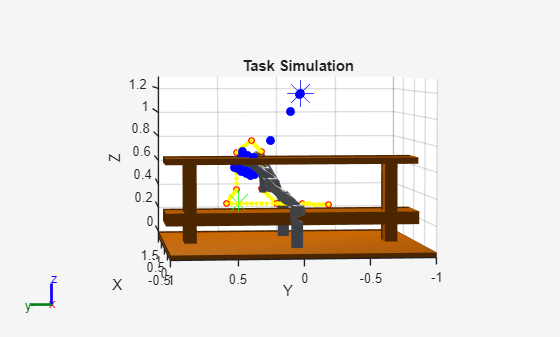

% time step
Ts = 0.2;
timeInterval = timeStep(1):Ts:timeStep(end);

motionModel = jointSpaceMotionModel('RigidBodyTree', robotRBT);

targetStates = [positions;velocities;accelerations]';
[t, states] = ode15s(@(t,state) timeBasedInput_Robot(motionModel, timeStep, targetStates, t, state), timeInterval, xInit);

% visualization
for i=1:height(states)
    show(robotRBT, states(i,1:joint_qty)', 'PreservePlot', false, 'Frames', 'off');

    % plot end-effector poses
    poseCurr = getTransform(robotRBT, states(i,1:joint_qty)', endEff);
    plot3(poseCurr(1,4), poseCurr(2,4), poseCurr(3,4), 'b.', 'MarkerSize', 20)
    
    % obstacle robot
    obst_dynamic = show(obst_robot, robotStateAll(i,1:7)', PreservePlot=false, Frames="off", Position=[1 0 0 pi], Visuals="on");

    drawnow;
end

## Design: Non-linear MPC

The state equation defines a model capable of computing state predictions based on the relationship between current joint positions $q
$ and  velocities $\dot{q}$ subject to control input acceleration $\ddot{q}$.

- Output: $x = [q, \dot{q}]$

- States: $x = [q, \dot{q}]$

- Input: $u = \ddot{q}$

Hence, the state equation is modelled as:


$$\dot{\mathit{\mathbf{x}}} =\textrm{Ax}+\textrm{Bu}$$


% generateNMPC;

### Closed-Loop Trajectory Planning

% obstacles = staticObst;
% obst_bodies = obst_robot.Bodies;
% 
% for i=1:length(obst_bodies)
%     if ~isempty(obst_bodies{i}.Collisions)
%         obst_transform = getTransform(obst_robot, robotStateAll(1,1:7)', obst_bodies{i}.Name);
%         for j=1:length(obst_bodies{i}.Collisions)
%             collision_obj = obst_bodies{i}.Collisions{j};
%             collision_obj.Pose = obst_transform * obst_bodies{i}.Collisions{j}.Pose;
% 
%             obstacles{end+1} = collision_obj;
%         end
%     end
% end

Simulation initial conditions

% maxIteration = 50;
% uInit = zeros(1, joint_qty);
% mv = uInit;
% time = 0;
% goalReached = false;

Initialize data matrices

% positions = zeros(joint_qty, maxIteration);
% positions(:,1) = xInit(1:joint_qty)';
% 
% velocities = zeros(joint_qty, maxIteration);
% velocities(:,1) = xInit(joint_qty+1:end);
% 
% accelerations = zeros(joint_qty, maxIteration);
% accelerations(:,1) = uInit';
% 
% timeStep = zeros(1, maxIteration);
% timeStep(:,1) = time;
% 
% x = xInit;
% options = nlmpcmoveopt;
% for iteration=1:maxIteration
%     disp(['Calculating control at timestep: ', num2str(iteration)])
% 
%     % optimize next trajectory point
%     [mv, options, info] = nlmpcmove(n_mpc, x, mv, [], [], options)
% 
%     % check for failed trajectory generations
%     if info.ExitFlag < 0
%         disp('Failed to compute a feasible trajectory. Aborting...')
%         break
%     end
% 
%     % update states and time
%     x = info.Xopt(2,:);
%     time = time + n_mpc.Ts;
% 
%     % log trajectory
%     positions(:,iteration+1) = x(1:joint_qty)';
%     velocities(:,iteration+1) = x(joint_qty+1:end)';
%     accelerations(:,iteration+1) = info.MVopt(2,:)';
%     timeStep(iteration+1) = time;
% 
%     % check if at desired pose
%     tolerance = 0.03;
%     jointFinal_i = info.Xopt(2,1:joint_qty);
%     taskFinal_i = getTransform(robotRBT, jointFinal_i', endEff);
%     anglesFinal_i = rotm2eul(taskFinal_i(1:3,1:3), "XYZ");
%     poseFinal_i = [taskFinal_i(1:3,4);anglesFinal_i'];
%     e_end = abs([poseEnd(1:3)-poseFinal_i(1:3); angdiff(poseFinal_i(4:6), poseEnd(4:6))]);
%     flag = ones(size(Qt,1), 1) & diag(Qt);
% 
%     if all(e_end(flag) < tolerance)
%         disp('Target configuration reached.')
%         break
%     end
% 
%     % update obstacle pose
%     obst_currTrans = getTransform(obst_robot, robotStateAll(iteration+1,1:7)', endEff)
%     %obstacles = [staticObst, {obst_currTrans}];
% 
%     n_mpc.Optimization.CustomIneqConFcn = @(X,U,e,data) inequalityConstraint(X,data,safety_dist,obstacles,robotRBT);
%     n_mpc.Jacobian.CustomIneqConFcn = @(X,U,e,data) jacobianInequalityConstraint(X,data,obstacles,robotRBT);
% end

### Joint-Space Simulation

### Final Visual Simulation